# Goertzel Probabilty of Detection

clear                                  % Clear all data stored in variables
Am = 1;                                % 1V Amplitude     
SR = 48000;                            % 48 KHz Smapling Rate
f0 = 13e+3;                            % 20 KHz
f1 = 10e+3;                            % 10 KHz
f2 = 4e+3;                             % 10 KHz
duration = (127/SR);                   % ~ 2.6 ms 
t = 0:1/SR:duration;                   % Time Vector

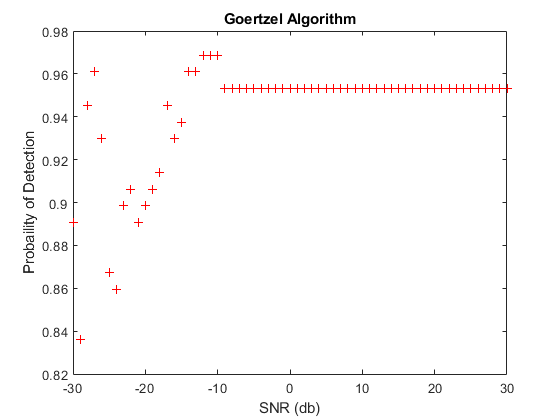

sinusPulse = Am*sin(2*pi*f0*t);  % Signal with multiple frequencies
mySNR = -30:30;
snrValues(sinusPulse,mySNR,100)

function snrValues(yourSignal,snr,threshold) 
    f0 = 13e+3;
    SR = 48000;
   for i = 1:length(snr)
            yourSignal = awgn(yourSignal,snr(i));
            find_PD_GA(f0,SR,yourSignal,threshold);        
            load Pd_GA.mat Pd   
            plot(snr(i),Pd,'r+');
            hold on
            title('Goertzel Algorithm')
            xlabel('SNR (db)')
            ylabel('Probaility of Detection')
   end
   hold off
end


function find_PD_GA(f0,sampleRate,noisySignal,threshold)
    N = length(noisySignal);
    Magnitude(length(noisySignal)) = 0; 
    Pdga(100) = 0;
    for i = 1:100
        k = round(0.5 + N*f0/sampleRate);
        w = 2*pi*k/N;
        cosine = cos(w);
        coeff = 2*cosine;
        Q2 = 0;
        Q1 = 0;
        for j = 1:N
            Q0 = noisySignal(j) + coeff*Q1 - Q2;
            Q2 = Q1;
            Q1 = Q0;
            Magnitude(j) = sqrt(Q1*Q1 + Q2*Q2 - Q1*Q2*coeff);
        end
        Pdg = Magnitude > threshold;
        Pdga(i) = sum(Pdg)/N;
    end
    Pd = sum(Pdga)/100;
    save PD_GA.mat Pd
end

